# Octave Band Filtering: Lab P-14: Lab Exersize 4: Bandpass Filter Design

% % housekeeping
% clear
% clc
% close all


## 4.1 Simple Bandpass Filter Design

% This section covers a basic filter design of various lengths, which results in different passband widths.

## 4.1a

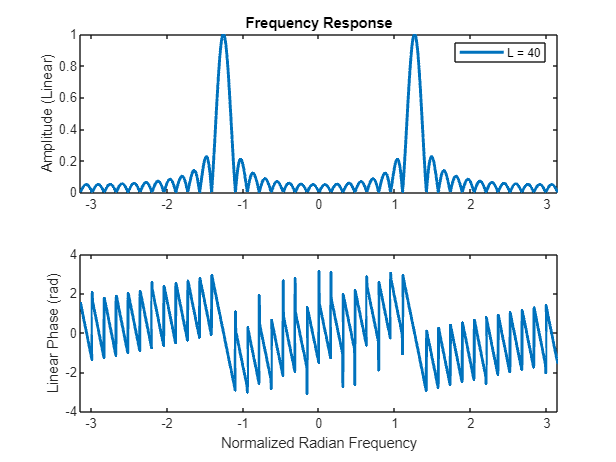

% Generate a bandpass filter with a center frequency of 0.4pi and filter
% length L = 40. Plot the magnitude and phase of the frequency response.
% Filter should be constructed using h(n) = 2*cos(wc*n)/L; Lots of design
% has been turned into functions. Reference functions for details.

L = 40;
[start_40, stop_40, width_40, H_40, HH_40, ~, ww, hh_40] = simpleFilterDesignAndAnalysis(L);

% plot frequency response
figure()
subplot(2,1,1);
plot(ww, abs(HH_40), 'LineWidth', 2)
title('Frequency Response')
ylabel('Amplitude (Linear)')
legend('L = 40')
xlim([-pi pi]);
subplot(2,1,2);
plot(ww, angle(HH_40), 'LineWidth', 2)
ylabel('Linear Phase (rad)')
xlabel('Normalized Radian Frequency')
xlim([-pi pi]);

## 4.1b

% Determine the passband of the filter from 4.1a using the 0.5*max level
% definition. NOTE: calculations are done inside the function used in 4.1a.

disp('The following data applies to the filter of length 40.')

The following data applies to the filter of length 40.


disp(['The starting freq is: ' , num2str(start_40)])

The starting freq is: 1.1655


disp(['The stopping freq is: ' , num2str(stop_40)])

The stopping freq is: 1.3509


disp(['The bandwidth is: ' , num2str(width_40)])

The bandwidth is: 0.18535


disp('All values are in radians.')

All values are in radians.


## 4.1c

% Perform 4.1a and 4.1b again with filters of length 20 and 80 and explain
% how the bandwidth is related to filter length L.

%Orignal signal so we can purely run this section independently
L = 40;
[start_40, stop_40, width_40, H_40, HH_40, ~, ww, ~] = simpleFilterDesignAndAnalysis(L);

% calculate frequency response and bandwidth data using function for each
% length.
L = 20;
[start_20, stop_20, width_20, H_20, HH_20, ~, ~, ~] = simpleFilterDesignAndAnalysis(L);
L = 80;
[start_80, stop_80, width_80, H_80, HH_80, w, ~, ~] = simpleFilterDesignAndAnalysis(L);

% display bandwidth data for L = 20
disp('The following data applies to the filter of length 20.')

The following data applies to the filter of length 20.


disp(['The starting freq is: ' , num2str(start_20)])

The starting freq is: 1.0713


disp(['The stopping freq is: ' , num2str(stop_20)])

The stopping freq is: 1.4483


disp(['The bandwidth is: ' , num2str(width_20)])

The bandwidth is: 0.37699


disp('All values are in radians.')

All values are in radians.



% display bandwidth data for L = 80
disp('The following data applies to the filter of length 80.')

The following data applies to the filter of length 80.


disp(['The starting freq is: ' , num2str(start_80)])

The starting freq is: 1.2095


disp(['The stopping freq is: ' , num2str(stop_80)])

The stopping freq is: 1.3038


disp(['The bandwidth is: ' , num2str(width_80)])

The bandwidth is: 0.094248


disp('All values are in radians.')

All values are in radians.


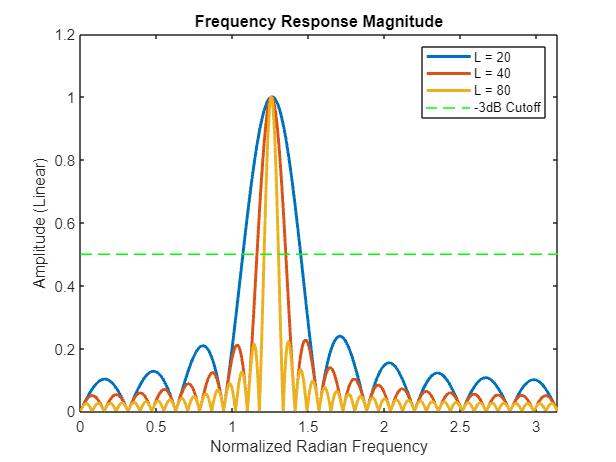


% Now overlay frequency response plot for visual reference.
figure()
plot(w, abs(H_20), 'LineWidth', 2)
hold on
plot(w, abs(H_40), 'LineWidth', 2)
plot(w, abs(H_80), 'LineWidth', 2)
plot(linspace(0, pi, 1024), 0.5 * ones(1, 1024), 'g--');
hold off
title('Frequency Response Magnitude')
ylabel('Amplitude (Linear)')
xlabel('Normalized Radian Frequency')
legend('L = 20', 'L = 40', 'L = 80','-3dB Cutoff')
xlim([0 pi]);

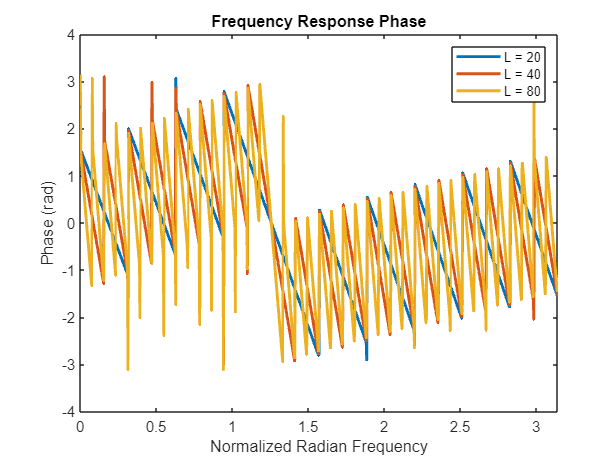


figure()
plot(w, angle(H_20), 'LineWidth', 2)
hold on
plot(w, angle(H_40), 'LineWidth', 2)
plot(w, angle(H_80), 'LineWidth', 2)
hold off
title('Frequency Response Phase')
ylabel('Phase (rad)')
xlabel('Normalized Radian Frequency')
legend('L = 20', 'L = 40', 'L = 80')
xlim([0 pi]);


% From these figures, it is seen that passband width is inversely
% proportional to filter length L. For example, if L increases, bandwidth
% decreases. From the calculated data, you can see further that the
% proportionality constant is nearly 1. Meaning that if L is doubled, then
% the bandwidth is nearly halved, and vice versa.


## Passing a musical signal through the 3 Filters in 4.2 c (Not part of the assignment)

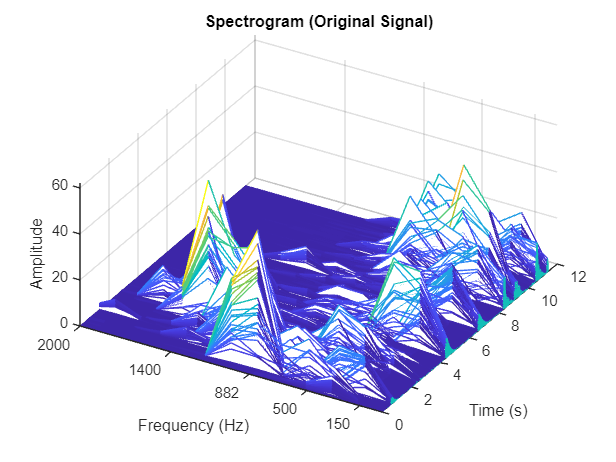

% Making a short version for presentation
[y_short, Fs] = audioread('rudenko_02.mp4');
y_short = y_short(1:500000); %Makes the song 11 seconds long going from 1:500k
audiowrite('rudenko_shortened.wav', y_short, Fs);
% sound(y_short,Fs)

% Reading in Piano Music
[y, Fs] = audioread('rudenko_shortened.wav');

% Passing Rudenko Piano through L = 80 Filter
L = 80;
[start_80, stop_80, width_80, H_80, HH_80, ~, ~, hh_80] = musicAnalysis(L);
x80 = conv(y, hh_80);
x80 = real(x80);
audiowrite('rudenko_Filtered_80.wav', x80, Fs);
% sound(x80,Fs)  %--- Uncomment to hear this sound

% Passing Rudenko Piano through L = 300 Filter
L = 300;
[start_300, stop_300, width_300, H_300, HH_300, ~, ww, hh_300] = musicAnalysis(L);
x300 = conv(y, hh_300);
x300 = real(x300);
audiowrite('rudenko_Filtered_300.wav', x300, Fs);
% sound(x300,Fs) %--- Uncomment to hear this sound

% Passing Rudenko Piano through L = 1000 Filter
L = 1000;
[start_1000, stop_1000, width_1000, H_1000, HH_1000, w, ~, hh_1000] = musicAnalysis(L);
x1000 = conv(y, hh_1000);
x1000 = real(x1000);
audiowrite('rudenko_Filtered_1000.wav', x1000, Fs);
% sound(x1000,Fs)  %--- Uncomment to hear this sound

[xsteady, Fs] = audioread('rudenko_shortened.wav');
Nfft = 2^nextpow2(length(xsteady));
Nspec = 256;
wspec = hamming(Nspec);
Noverlap = Nspec/2;
[Ssteady, fspec, tspec] = spectrogram(xsteady, wspec, Noverlap, Nspec, Fs);

figure;
waterplot(Ssteady,fspec,tspec)
title("Spectrogram (Original Signal)")
xlim([0 2000]);
xticks([150 500 882 1400 2000]);

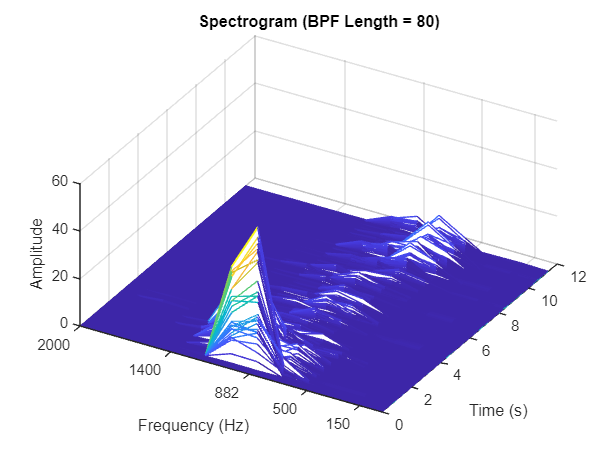


[xsteady, Fs] = audioread('rudenko_Filtered_80.wav');
[Ssteady, fspec, tspec] = spectrogram(xsteady, wspec, Noverlap, Nspec, Fs);

figure;
waterplot(Ssteady,fspec,tspec)
title("Spectrogram (BPF Length = 80)")
xlim([0 2000]);
xticks([150 500 882 1400 2000]);

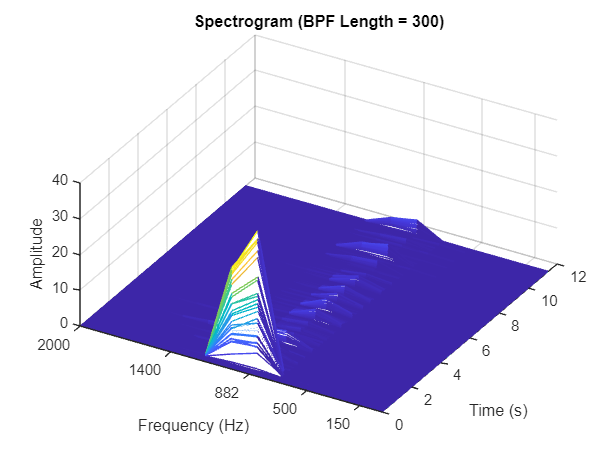


[xsteady, Fs] = audioread('rudenko_Filtered_300.wav');
[Ssteady, fspec, tspec] = spectrogram(xsteady, wspec, Noverlap, Nspec, Fs);

figure;
waterplot(Ssteady,fspec,tspec)
title("Spectrogram (BPF Length = 300)")
xlim([0 2000]);
xticks([150 500 882 1400 2000]);

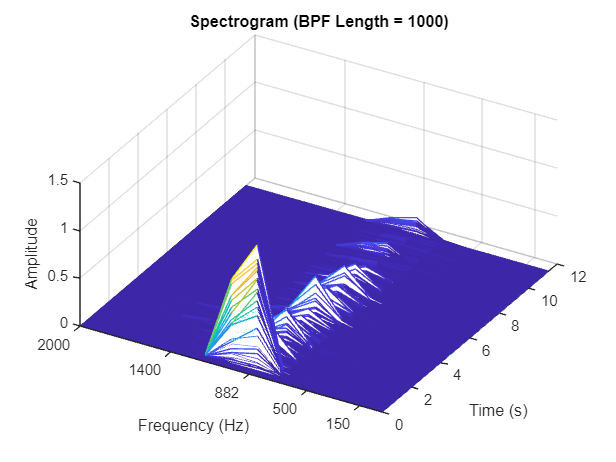


[xsteady, Fs] = audioread('rudenko_Filtered_1000.wav');
[Ssteady, fspec, tspec] = spectrogram(xsteady, wspec, Noverlap, Nspec, Fs);

figure;
waterplot(Ssteady,fspec,tspec)
title("Spectrogram (BPF Length = 1000)")
xlim([0 2000]);
xticks([150 500 882 1400 2000]);

## 4.2 A Better BFP

% This section focuses on now applying a hamming window to the cosine
% filter to reduce stopband ripples. The frequency responses are plotted
% and bandwidths calculated just like as in 4.1. filter lengths are 21, 41,
% and 81. Then a signal is filtered roughly by hand, and the filtering is
% explained.

% % housekeeping
% clear
% clc
% close


## 4.2a

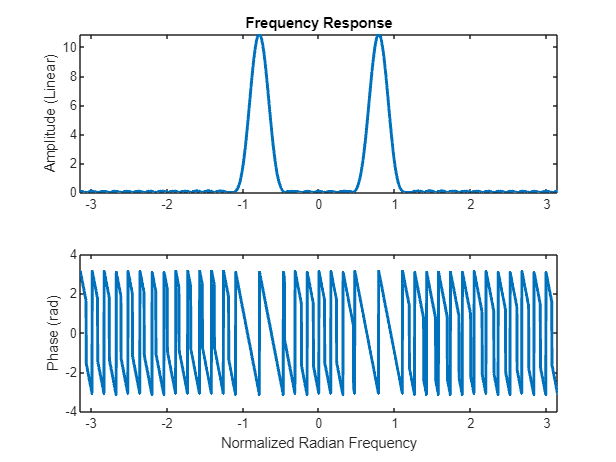

% Generate a Hamming bandpass filter with center frequency wc = 0.25pi, and
% filter length L = 41. Also determine the Frequency response to a list of
% specific frequencies. Reference functions for details.

L = 41;
[start_41, stop_41, width_41, H_41, HH_41, ~, ww, hh_41] = hammingFilterDesignAndAnalysis(L);

% plot frequency response
figure()
subplot(2,1,1);
plot(ww, abs(HH_41), 'LineWidth', 2)
title('Frequency Response')
ylabel('Amplitude (Linear)')
xlim([-pi pi]);
subplot(2,1,2);
plot(ww, angle(HH_41), 'LineWidth', 2)
ylabel('Phase (rad)')
xlabel('Normalized Radian Frequency')
xlim([-pi pi]);


% Frequency response to specific frequencies
HH_test = freqz(hh_41, 1, pi.*[0, 0.1, 0.25, 0.4, 0.5, 0.75]);
HH_test_abs = abs(HH_test);
HH_test_angle = angle(HH_test);

% Summarize data in a table
T = array2table([HH_test_abs;HH_test_angle],'VariableNames',{'0','0.1pi','0.25pi','0.4pi','0.5pi','0.75pi'},'RowName',{'Mag','Phase'}); 
disp(T) 

               0        0.1pi     0.25pi     0.4pi      0.5pi     0.75pi 
             ______    _______    ______    _______    _______    _______

    Mag        0.08       0.08     10.88       0.08       0.08       0.08
    Phase    3.1416    -3.1416    3.1416    -3.1416    -3.1416    -3.1416



## 4.2b

% Determine the width of the L = 41 filter. Then generate 2 more with L =
% 21 and 81. Plot and compare their passbands. Again explain the
% relationship between L and passband width.

% calculate frequency response and bandwidth data using function for each
% length.
L = 21;
[start_21, stop_21, width_21, H_21, HH_21, ~, ~, ~] = hammingFilterDesignAndAnalysis(L);
L = 81;
[start_81, stop_81, width_81, H_81, HH_81, w, ~, ~] = hammingFilterDesignAndAnalysis(L);

% display bandwidth data for L = 41
disp('The following data applies to the filter of length 41.')

The following data applies to the filter of length 41.


disp(['The starting freq is: ' , num2str(start_41)])

The starting freq is: 0.64717


disp(['The stopping freq is: ' , num2str(stop_41)])

The stopping freq is: 0.92363


disp(['The bandwidth is: ' , num2str(width_41)])

The bandwidth is: 0.27646


disp('All values are in radians.')

All values are in radians.



% display bandwidth data for L = 21
disp('The following data applies to the filter of length 21.')

The following data applies to the filter of length 21.


disp(['The starting freq is: ' , num2str(start_21)])

The starting freq is: 0.50265


disp(['The stopping freq is: ' , num2str(stop_21)])

The stopping freq is: 1.0681


disp(['The bandwidth is: ' , num2str(width_21)])

The bandwidth is: 0.56549


disp('All values are in radians.')

All values are in radians.



% display bandwidth data for L = 81
disp('The following data applies to the filter of length 81.')

The following data applies to the filter of length 81.


disp(['The starting freq is: ' , num2str(start_81)])

The starting freq is: 0.71628


disp(['The stopping freq is: ' , num2str(stop_81)])

The stopping freq is: 0.85451


disp(['The bandwidth is: ' , num2str(width_81)])

The bandwidth is: 0.13823


disp('All values are in radians.')

All values are in radians.


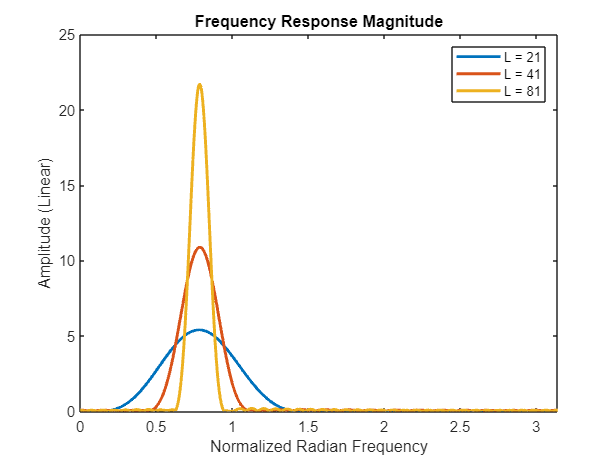


% Now overlay frequency response plot for visual reference.
figure()
plot(w, abs(H_21), 'LineWidth', 2)
hold on
plot(w, abs(H_41), 'LineWidth', 2)
plot(w, abs(H_81), 'LineWidth', 2)
hold off
title('Frequency Response Magnitude')
ylabel('Amplitude (Linear)')
xlabel('Normalized Radian Frequency')
legend('L = 21', 'L = 41', 'L = 81')
xlim([0 pi]);

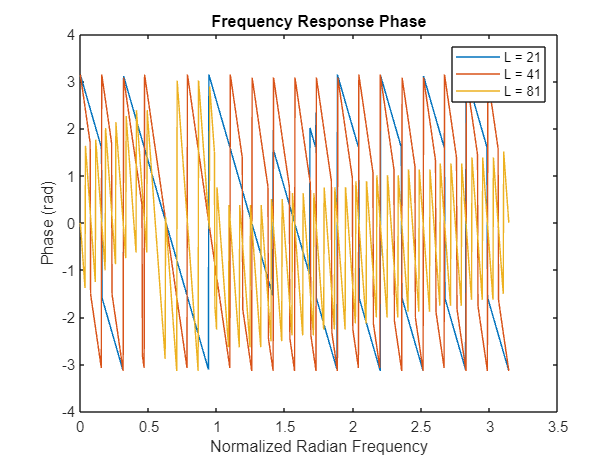


figure()
plot(w, angle(H_21))
hold on
plot(w, angle(H_41))
plot(w, angle(H_81))
hold off
title('Frequency Response Phase')
ylabel('Phase (rad)')
xlabel('Normalized Radian Frequency')
legend('L = 21', 'L = 41', 'L = 81')


% Just like that in 4.1, it is seen that passband width is inversely
% proportional to filter length L. For example, if L increases, bandwidth
% decreases. From the calculated data, you can see further that the
% proportionality constant is nearly 1. Meaning that if L is doubled, then
% the bandwidth is nearly halved, and vice versa.
% Notably here, the gain increases as bandwidth is narrowed, corresponding
% to a concentration of the same power to a smaller bandwidth. 

## Extra Plot showing Hamming Window from 4.2 vs Sinusoid (rectangular window) from 4.1

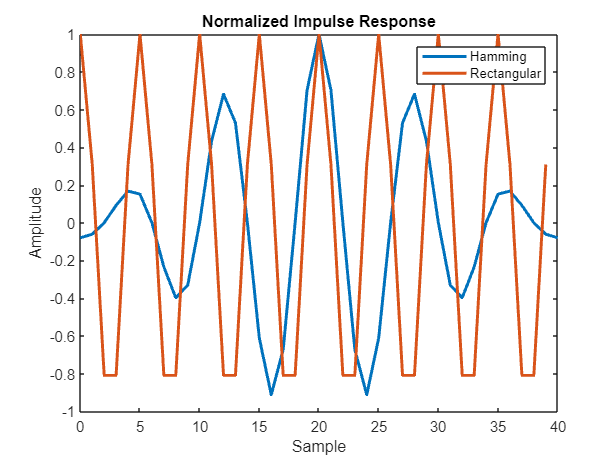

% generate filter coefficients plot
figure()
plot(0:length(hh_41) - 1, hh_41, 'LineWidth', 2)
hold on
plot(0:length(hh_40) - 1, hh_40.*20, 'LineWidth', 2)
title('Normalized Impulse Response')
ylabel('Amplitude')
xlabel('Sample')
legend('Hamming', 'Rectangular')

## 4.2c

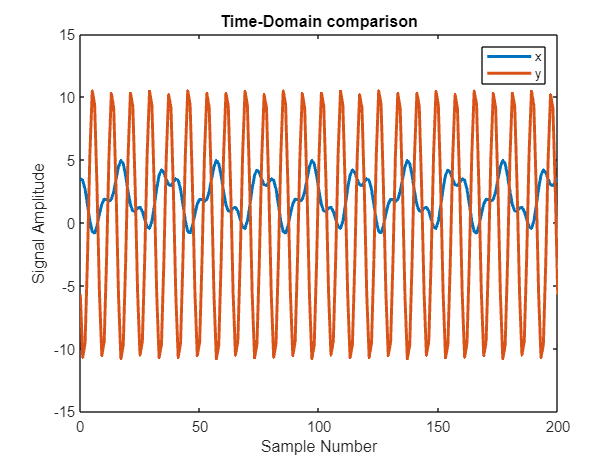

% The output signal y[n] of the length-41 FIR bandpass filter (BPF) in response
% to an input signal x[n] can be obtained by convolving the input signal with
% the filter's impulse response h[n]:
%
% y[n] = x[n] * h[n]
%
% Given the input signal:
%
% x[n] = 2 + 2 * cos(0.1 * pi * n + pi/3) + cos(0.25 * pi * n - pi/3)
%
% And assuming that the filter's impulse response is denoted as h[n], the output
% signal y[n] is obtained by convolving x[n] with h[n].
%
% In practice, the convolution operation can be performed using the formula:
%
% y[n] = ∑ (x[k] * h[n - k])   where the sum is over k from -∞ to ∞
%
% However, since the filter length is finite (41 in this case), the sum will be
% limited to the range of k such that 0 ≤ k ≤ 40.

% Given an input signal, filter it with the L = 41 filter 'by hand' by
% applying the affect of filter gain and phase to th input signal. signal:
% x = 2 + 2.*cos(0.1.*pi.*n + pi./3) + cos(0.25.*pi.*n - pi./3);

% at each frequency, the gains of the signal and filter are multiplied and
% the phases are added.

n = 0:200;
x = 2 + 2.*cos(0.1.*pi.*n + pi./3) + cos(0.25.*pi.*n - pi./3);

% Inspecting signal, we have amplitudes and phases:
x_A = [2, 2, 1];
x_P = [0, pi./3, -pi./3];

% Filter effects at these same frequencies pulled from above.
h_A = HH_test_abs(1:3);
h_P = HH_test_angle(1:3);

% multiply and add phases:
y_A = x_A.*h_A;
y_P = x_P + h_P;

% Apply each component amplitude and phase to corresponding frequency.
% Output signal is y.
y = y_A(1).*cos(y_P(1)) + y_A(2).*cos(0.1.*pi.*n + y_P(2)) + y_A(3).*cos(0.25.*pi.*n + y_P(3));

% plot to see signal changes in time-domain
figure()
plot(n, x, 'LineWidth', 2);
hold on
plot(n, y, 'LineWidth', 2);
hold off
legend('x','y')
title('Time-Domain comparison')
ylabel('Signal Amplitude')
xlabel('Sample Number')

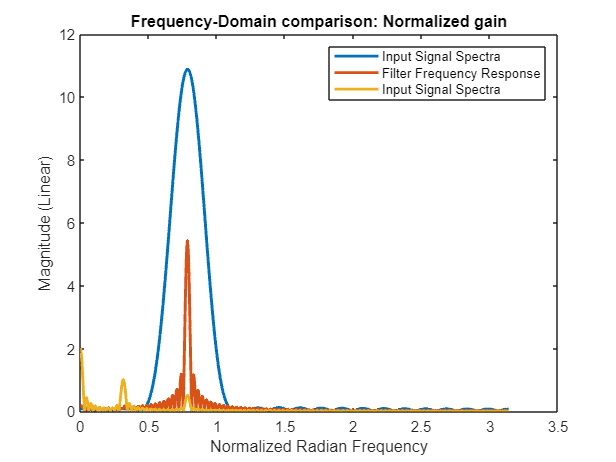


XX = fft([x, zeros(1,9999)]);
YY = fft([y, zeros(1,9999)]);
XX = XX(1:end-floor(length(XX)/2));
YY = YY(1:end-floor(length(YY)/2));

figure()
plot(w, abs(H_41), 'LineWidth', 2)
hold on
plot(linspace(0,pi,floor(length(XX))), abs(YY)/length(n), 'LineWidth', 2)
plot(linspace(0,pi,floor(length(XX))), abs(XX)/length(n), 'LineWidth', 2)
legend('Input Signal Spectra','Filter Frequency Response','Input Signal Spectra')
title('Frequency-Domain comparison: Normalized gain')
ylabel('Magnitude (Linear)')
xlabel('Normalized Radian Frequency')


% ww = 0 was not in the passband and is seen as heavily attenuated in the plots.
% ww = 0.1pi was not in the passband and is seen as heavily attenuated in the plots.
% ww = 0.25 was in the passband, where gain is about 10.8, and is seen as
% heavily amplified. This results in the output signal being nearly just
% that component entirely, which is what is seen in the time-domain output
% plot.



## 4.2d

% Use the frequency response and passband width to explain how the
% component at w = 0.25pi passed and others were rejected.

% Looking at the figure, we can see the strong passband component
% completely covering the input signal component at 0.25pi, indicating alot
% of that power will pass thought while all outside will be rejected. 
% From the calculations earlier, the passband for this filter goes from
% about 0.2pi to 0.29pi. The only frequency component in this range is
% 0.25pi, which is amplified. All other frequency components are far from
% this range, and the hamming window stopband is very low, causing
% frequencies far from the passband range to be heavily attenuated.


## Functions

function [start, stop, width, H, HH, w, ww, hh] = simpleFilterDesignAndAnalysis(L)
    % This function creates filters using the simple equation, h(n) =
    % 2*cos(wc*n)/L;, and outputs the start, stop, and bandwidth of the
    % filter in radians, with the bandwidth defined as being half the
    % maximum power. It also returns the single-side and dual-side frequency response of
    % the filter. It also returnes the frequency range of the frequency
    % response for plotting.

    reso = 1000;                % set resolution of frequency response
    n = 0:L - 1;
    ww = -pi:(pi/reso):pi;      % set omega range for frequency response plot
    wc = 0.4.*pi;               % set center frequency in radians
    
    hh = 2.*cos(wc.*n)./L;      % calculate impulse response  
    
    HH = freqz(hh, 1, ww);      % calculate frequency response
    
    % Now find bandwidth data
    
    w = 0:(pi/reso):pi;         % set omega range for single-side bandwidth calculation
    H = freqz(hh, 1, w);        % calculate single-side frequency response

    H_abs = abs(H);
    PB_lvl = 0.5*max(H_abs);    % calculate half-power threshold
    
    % locate indexes where amplitude starts and stops exceeding half
    % amplitude
    startBand_index = find(H_abs>PB_lvl, 1, 'first');
    stopBand_index = find(H_abs>PB_lvl, 1, 'last');
    
    % determine start, stop frequencies and bandwidth.
    startBand_freq = (w(startBand_index));
    stopBand_freq = (w(stopBand_index));
    passBand_width = stopBand_freq - startBand_freq;

    start = startBand_freq;
    stop = stopBand_freq;
    width = passBand_width;

end % end simpleFilterDesignAndAnalysis

function [start, stop, width, H, HH, w, ww, hh] = musicAnalysis(L)
    % This function is identical to the function above, but w_c 
    % is changed to 0.04pi instead of 0.4pi.

    reso = 1000;                % set resolution of frequency response
    n = 0:L - 1;
    ww = -pi:(pi/reso):pi;      % set omega range for frequency response plot
    wc = 0.04.*pi;               % set center frequency in radians
    
    hh = 2.*cos(wc.*n)./L;      % calculate impulse response  
    
    HH = freqz(hh, 1, ww);      % calculate frequency response
    
    % Now find bandwidth data
    
    w = 0:(pi/reso):pi;         % set omega range for single-side bandwidth calculation
    H = freqz(hh, 1, w);        % calculate single-side frequency response

    H_abs = abs(H);
    PB_lvl = 0.5*max(H_abs);    % calculate half-power threshold
    
    % locate indexes where amplitude starts and stops exceeding half
    % amplitude
    startBand_index = find(H_abs>PB_lvl, 1, 'first');
    stopBand_index = find(H_abs>PB_lvl, 1, 'last');
    
    % determine start, stop frequencies and bandwidth.
    startBand_freq = (w(startBand_index));
    stopBand_freq = (w(stopBand_index));
    passBand_width = stopBand_freq - startBand_freq;

    start = startBand_freq;
    stop = stopBand_freq;
    width = passBand_width;

end % end musicAnalysis

function [start, stop, width, H, HH, w, ww, hh] = hammingFilterDesignAndAnalysis(L)
    % This function creates filters using the hamming equation, 
    % h1 = (0.54 - 0.46.*cos(2.*pi.*n./(L - 1)));
    % h2 = cos(wc.*(n - (L - 1)./2));
    % h = h1.*h2;,
    % and outputs the start, stop, and bandwidth of the
    % filter in radians, with the bandwidth defined as being half the
    % maximum power. It also returns the single-side and dual-side frequency response of
    % the filter. It also returnes the frequency range of the frequency
    % response for plotting.

    reso = 1000;                % set resolution of frequency response
    n = 0:L - 1;
    ww = -pi:(pi/reso):pi;      % set omega range for frequency response plot
    wc = 0.25.*pi;              % set center frequency in radians
    
    % calculate impulse response  
    h1 = (0.54 - 0.46.*cos(2.*pi.*n./(L - 1)));
    h2 = cos(wc.*(n - (L - 1)./2));
    hh = h1.*h2;
    
    HH = freqz(hh, 1, ww);      % calculate frequency response
    
    % Now find bandwidth data
    
    w = 0:(pi/reso):pi;         % set omega range for single-side bandwidth calculation
    H = freqz(hh, 1, w);        % calculate single-side frequency response

    H_abs = abs(H);
    PB_lvl = 0.5*max(H_abs);    % calculate half-power threshold
    
    % locate indexes where amplitude starts and stops exceeding half
    % amplitude
    startBand_index = find(H_abs>PB_lvl, 1, 'first');
    stopBand_index = find(H_abs>PB_lvl, 1, 'last');
    
    % determine start, stop frequencies and bandwidth.
    startBand_freq = (w(startBand_index));
    stopBand_freq = (w(stopBand_index));
    passBand_width = stopBand_freq - startBand_freq;

    start = startBand_freq;
    stop = stopBand_freq;
    width = passBand_width;

end % end hammingFilterDesignAndAnalysis

function waterplot(s,f,t)
% Waterfall plot of spectrogram
    waterfall(f,t,abs(s)'.^2)
    set(gca,XDir="reverse",View=[30 50])
    xlabel("Frequency (Hz)")
    ylabel("Time (s)")
    zlabel("Amplitude")
end